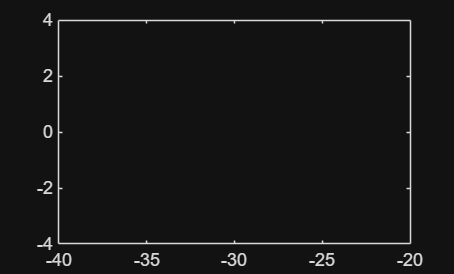

c = 12.75;  % Länge Oberarm
e = 9;      % Abstand Oberarm Mitte
d = 30;     % Länge Unterarm
f = 4.25;   % Abstand Unterarm Mitte

m = e - f;  % vereinfachter Abstand Oberarm Mitte (Angriffspunkte Plattform nach innen auf D versetzt)


figure(1);
for i = -20:-0.1:-40
    D = [0 0 i];
    xD = D(1);
    yD = D(2);
    zD = D(3);
    
    u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;
    
    a = yD + m;
    b = u / (2 * c);
    
    alpha1 = 2*atan((zD-sqrt(zD^2 + a^2 - b^2)) / (a + b));

    plot(i, alpha1)
    hold on
end

c = 12.75;  % Länge Oberarm
e = 9;      % Abstand Oberarm Mitte
d = 30;     % Länge Unterarm
f = 4.25;   % Abstand Unterarm Mitte

m = e - f;

i_vals = -20:-0.1:-40;
alpha_vals = zeros(size(i_vals));

for k = 1:length(i_vals)

    i = i_vals(k);

    D = [0 0 i];
    xD = D(1);
    yD = D(2);
    zD = D(3);
    
    u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;
    
    a = yD + m;
    b = u / (2 * c);
    
    alpha1 = 2*atan((zD - sqrt(zD^2 + a^2 - b^2)) / (a + b));

    alpha_vals(k) = alpha1;
end


figure
%plot(i_vals, alpha_vals.*100,'LineWidth',2)
%hold on
alpha_vals_deg = rad2deg(alpha_vals)

alpha_vals_deg =   156.4407  157.1214  157.7916  158.4517  159.1020  159.7431  160.3753  160.9990  161.6145  162.2222  162.8222  163.4151  164.0009  164.5799  165.1525  165.7188  166.2790  166.8334  167.3821  167.9254  168.4633  168.9962  169.5241  170.0473  170.5658  171.0798  171.5894  172.0949  172.5962  173.0936  173.5871  174.0769  174.5630  175.0456  175.5248  176.0006  176.4733  176.9427  177.4092  177.8726  178.3332  178.7910  179.2460  179.6984 -179.8518 -179.4045 -178.9596 -178.5171 -178.0769 -177.6390


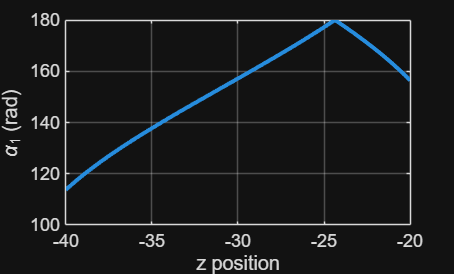

plot(i_vals, abs(alpha_vals_deg),'LineWidth',2)
xlabel('z position')
ylabel('\alpha_1 (rad)')
grid on

D12 = [(-0.5*xD + sqrt(3)/2 * yD) (-sqrt(3)/2 * xD - 0.5*yD) (zD)]

D12 =      0     0   -40


xD = D12(1);
yD = D12(2);
zD = D12(3);

u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;

a = yD + m;
b = u / (2 * c);

alpha2 = 2*atan((zD-sqrt(zD^2 + a^2 - b^2)) / (a + b))

alpha2 = -1.9848

alpha2 = mod(rad2deg(alpha2) + 236, 360)

alpha2 = 122.2819

D13 = [(-0.5*xD - sqrt(3)/2 * yD) (sqrt(3)/2 * xD - 0.5*yD) (zD)]

D13 =      0     0   -40


xD = D13(1);
yD = D13(2);
zD = D13(3);

u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;

a = yD + m;
b = u / (2 * c);

alpha3 = 2*atan((zD-sqrt(zD^2 + a^2 - b^2)) / (a + b))

alpha3 = -1.9848

alpha3 = mod(rad2deg(alpha3) + 236, 360)

alpha3 = 122.2819